Parameters

% จุดยึดบนโครง หน่วย mm
O1_x = 45;    O1_y = 0;
O2_x =  0;    O2_y = 0;
O3_x =  0;    O3_y = 45;
% ความยาวลิงก์ หน่วย mm
O3C = 40;                    % Link 2
O1A = 25;                    % Link 3
O2B = 20;                    % Link 4: input crank
BA  = 45;                    % Link 5: B ถึง A
AD  = 40;                    % Link 5: A ถึง D
DC  = 65;                    % Link 6: D ถึง C
DF  = 70;                    % Link 6: D ถึง F
bend = 120*pi/180;
q0 = 255*pi/180;             % มุมเริ่มต้นของข้อเหวี่ยงขาหลัง
rpm = 10;
omega4 = 2*pi*rpm/60;        % ขนาดความเร็วเชิงมุม rad/s
T = 60/rpm;                  % 6 วินาทีต่อรอบ
t0 = 0;                      % เวลาที่เลือกวิเคราะห์ หน่วย s

Equations

% จุด B บนข้อเหวี่ยง O2B
Bx = @(q) O2_x + O2B*cos(q);
By = @(q) O2_y + O2B*sin(q);
% สมการหาจุดตัดวงกลม
% r และ s คือรัศมีของวงกลม
% d คือระยะระหว่างศูนย์กลาง
% p คือระยะฉายตามแนวเส้นเชื่อมศูนย์กลาง
syms r s d p
eq = 2*d*p == d^2 + r^2 - s^2;
p_sol = solve(eq,p);
% จุด A: จุดตัดของวงกลมรอบ B และ O1
dx1 = @(q) O1_x - Bx(q);
dy1 = @(q) O1_y - By(q);
d1  = @(q) (dx1(q).^2 + dy1(q).^2).^0.5;
pA_sol = subs(p_sol,[r s],[BA O1A]);
p1 = @(q) subs(pA_sol,d,d1(q));
h1 = @(q) (BA^2 - p1(q).^2).^0.5;
% เลือกด้านของจุด A ตามไฟล์ขาหลัง
Ax = @(q) Bx(q) + (p1(q).*dx1(q) - h1(q).*dy1(q))./d1(q);
Ay = @(q) By(q) + (p1(q).*dy1(q) + h1(q).*dx1(q))./d1(q);
% จุด D: อยู่ต่อจาก A ตามแนว B->A
Dx = @(q) Ax(q) + (AD/BA)*(Ax(q)-Bx(q));
Dy = @(q) Ay(q) + (AD/BA)*(Ay(q)-By(q));
%จุด C: จุดตัดของวงกลมรอบ D และ O3
dx2 = @(q) O3_x - Dx(q);
dy2 = @(q) O3_y - Dy(q);
d2  = @(q) (dx2(q).^2 + dy2(q).^2).^0.5;
pC_sol = subs(p_sol,[r s],[DC O3C]);
p2 = @(q) subs(pC_sol,d,d2(q));
h2 = @(q) (DC^2 - p2(q).^2).^0.5;
% เลือกด้านของจุด C ตามไฟล์ขาหลัง
Cx = @(q) Dx(q) + (p2(q).*dx2(q) + h2(q).*dy2(q))./d2(q);
Cy = @(q) Dy(q) + (p2(q).*dy2(q) - h2(q).*dx2(q))./d2(q);
% จุด F: ปลายเท้าของลิงก์ 6
% ขาหลังใช้มุม theta6 + 120 องศา
cos6 = @(q) (Cx(q)-Dx(q))/DC;
sin6 = @(q) (Cy(q)-Dy(q))/DC;
Fx = @(q) Dx(q) + DF*(cos6(q)*cos(bend) - sin6(q)*sin(bend));
Fy = @(q) Dy(q) + DF*(sin6(q)*cos(bend) + cos6(q)*sin(bend));
syms t real
% ขาหลังหมุนตามเข็ม มุมข้อเหวี่ยงจึงลดลงตามเวลา
q_t = q0 - omega4*t;
% แถว 1 = A, แถว 2 = B, แถว 3 = C, แถว 4 = D, แถว 5 = F
% คอลัมน์ 1 = x และคอลัมน์ 2 = y
P_t = [Ax(q_t), Ay(q_t);
       Bx(q_t), By(q_t);
       Cx(q_t), Cy(q_t);
       Dx(q_t), Dy(q_t);
       Fx(q_t), Fy(q_t)];
V_t = diff(P_t,t);
Acc_t = diff(V_t,t);
P   = double(subs(P_t,t,t0));       % mm
V   = double(subs(V_t,t,t0))        % mm/s

V =    -5.4086   -7.6497
  -20.2303    5.4207
   23.0385   -0.1467
    7.7663  -19.2678
  -18.2904  -15.3202


Acc = double(subs(Acc_t,t,t0))      % mm/s^2

Acc =     9.0157    6.6701
    5.6765   21.1851
   18.0619  -13.3852
   11.9838   -6.2322
   15.3821    3.2881


position_F     = P(5,:)             % [xF yF]

position_F =    40.5577  -24.7764


velocity_F     = V(5,:)             % [vFx vFy]

velocity_F =   -18.2904  -15.3202


acceleration_F = Acc(5,:)           % [aFx aFy]

acceleration_F =    15.3821    3.2881


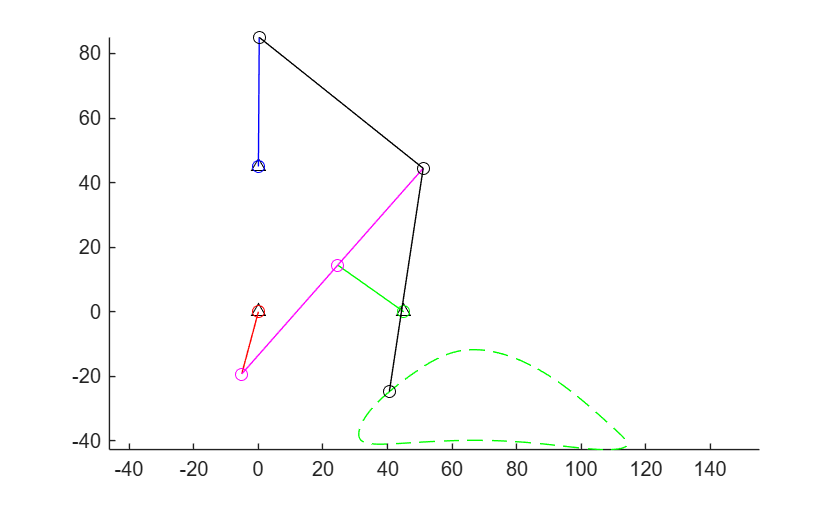

% ขาหลังหมุนตามเข็มครบหนึ่งรอบ
q_path = q0 - (0:1:360)*pi/180;
foot_x = double(Fx(q_path));
foot_y = double(Fy(q_path));
figure()
hold on
% วิถีปลายเท้า F
plot(foot_x,foot_y,'--g')
% จุดยึดบนโครง
plot(O1_x,O1_y,'^k')
plot(O2_x,O2_y,'^k')
plot(O3_x,O3_y,'^k')
% Link 2: O3-C
plot([O3_x P(3,1)], [O3_y P(3,2)], '-ob')
% Link 3: O1-A
plot([O1_x P(1,1)], [O1_y P(1,2)], '-og')
% Link 4: O2-B
plot([O2_x P(2,1)], [O2_y P(2,2)], '-or')
% Link 5: B-A-D
plot(P([2 1 4],1), P([2 1 4],2), '-om')
% Link 6: C-D-F
plot(P([3 4 5],1), P([3 4 5],2), '-ok')
axis equal
hold off

Velocity  Acceleration image

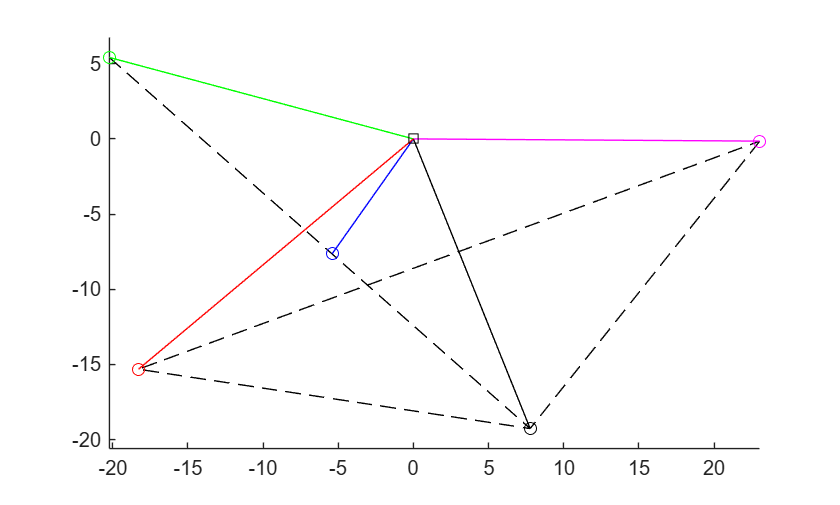

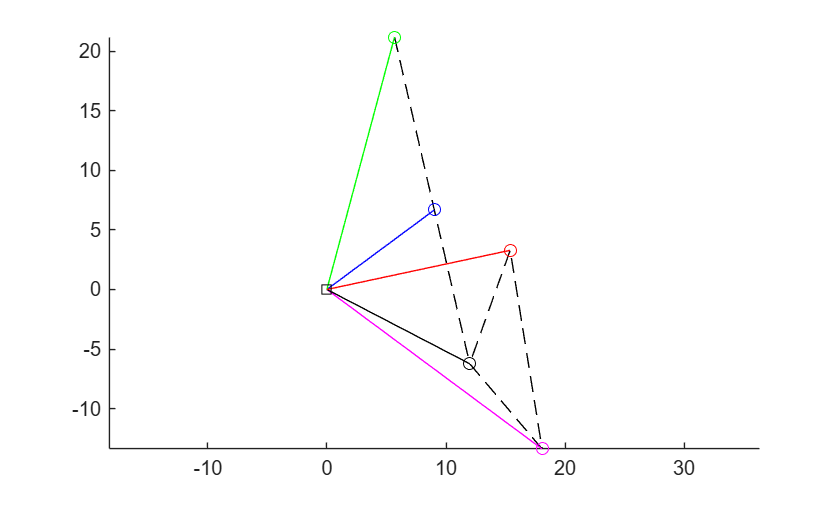

% รูปแรกใช้ V หน่วย mm/s
% รูปที่สองใช้ Acc หน่วย mm/s^2
% สี่เหลี่ยมดำคือขั้ว O และวงกลมสีคือปลายเวกเตอร์
% A = น้ำเงิน, B = เขียว, C = ม่วง, D = ดำ, F = แดง
for k = 1:2

    if k == 1
        U = V;
    else
        U = Acc;
    end

    figure()
    hold on
    plot(U([2 1 4],1),   U([2 1 4],2),   '--k')    % B-A-D
    plot(U([3 4 5 3],1), U([3 4 5 3],2), '--k')    % C-D-F-C
    plot([0 U(1,1)], [0 U(1,2)], '-b')
    plot([0 U(2,1)], [0 U(2,2)], '-g')
    plot([0 U(3,1)], [0 U(3,2)], '-m')
    plot([0 U(4,1)], [0 U(4,2)], '-k')
    plot([0 U(5,1)], [0 U(5,2)], '-r')
    plot(U(1,1),U(1,2),'ob')
    plot(U(2,1),U(2,2),'og')
    plot(U(3,1),U(3,2),'om')
    plot(U(4,1),U(4,2),'ok')
    plot(U(5,1),U(5,2),'or')
    plot(0,0,'sk')
    axis equal
    hold off
end

Force analysis

% หาแรงที่สลัก C และ D กระทำต่อลิงก์ 6
% กรณีโครงอยู่นิ่ง เท้า F ลอย และข้อต่อไม่มีแรงเสียดทาน
% ลิงก์ 2 เป็นแท่งตรงสม่ำเสมอ
% ลิงก์ 6 คิดเป็นแท่ง DC และ DF ที่มีมวลต่อความยาวเท่ากัน
g = 9.81;
m2 = 0.040;                     % kg มวลตัวอย่างของลิงก์ 2
m6 = 0.135;                     % kg มวลตัวอย่างของลิงก์ 6
C  = P(3,:)/1000;
D  = P(4,:)/1000;
F  = P(5,:)/1000;
O3 = [O3_x O3_y]/1000;
aC = Acc(3,:)/1000;
aD = Acc(4,:)/1000;
aF = Acc(5,:)/1000;

% link2
L2 = O3C/1000;
r2 = C-O3;
I2 = m2*L2^2/3;                 % โมเมนต์ความเฉื่อยรอบ O3
alpha2 = (r2(1)*aC(2) - r2(2)*aC(1))/L2^2;
%link6
Lc = DC/1000;
Lf = DF/1000;
r6 = C-D;
aCD = aC-aD;
alpha6 = (r6(1)*aCD(2) - r6(2)*aCD(1))/Lc^2;
% มวลของท่อน DC และ DF
mc = m6*Lc/(Lc+Lf);
mf = m6*Lf/(Lc+Lf);
% ตำแหน่งศูนย์กลางมวล
Gc = (D+C)/2;
Gf = (D+F)/2;
G6 = (mc*Gc + mf*Gf)/m6;
% ความเร่งศูนย์กลางมวล
aGc = (aD+aC)/2;
aGf = (aD+aF)/2;
aG6 = (mc*aGc + mf*aGf)/m6;
% โมเมนต์ความเฉื่อยของลิงก์ 6 รอบ G6
dc = Gc-G6;
df = Gf-G6;
I6 = mc*(Lc^2/12 + dc(1)^2 + dc(2)^2) ...
   + mf*(Lf^2/12 + df(1)^2 + df(2)^2);
syms RCx RCy RDx RDy
rc = C-G6;
rd = D-G6;
% ผลรวมแรงในแนว x และ y บนลิงก์ 6
eq1 = RCx + RDx == m6*aG6(1);
eq2 = RCy + RDy - m6*g == m6*aG6(2);
% ผลรวมโมเมนต์รอบ G6 ของลิงก์ 6
eq3 = rc(1)*RCy - rc(2)*RCx ...
    + rd(1)*RDy - rd(2)*RDx == I6*alpha6;
% ผลรวมโมเมนต์รอบ O3 ของลิงก์ 2
% แรงที่ C บนลิงก์ 2 เท่ากับ [-RCx,-RCy]
eq4 = -r2(1)*RCy + r2(2)*RCx ...
      - (r2(1)/2)*m2*g == I2*alpha2;
sol = solve([eq1 eq2 eq3 eq4],[RCx RCy RDx RDy]);
RC = double([sol.RCx sol.RCy])    % แรงที่ C บนลิงก์ 6 [Fx Fy], N

RC =     0.0035    0.3863


RD = double([sol.RDx sol.RDy])    % แรงที่ D บนลิงก์ 6 [Fx Fy], N

RD =    -0.0015    0.9373


W6 = [0 -m6*g];                   % น้ำหนักลิงก์ 6, N


Free body diagram

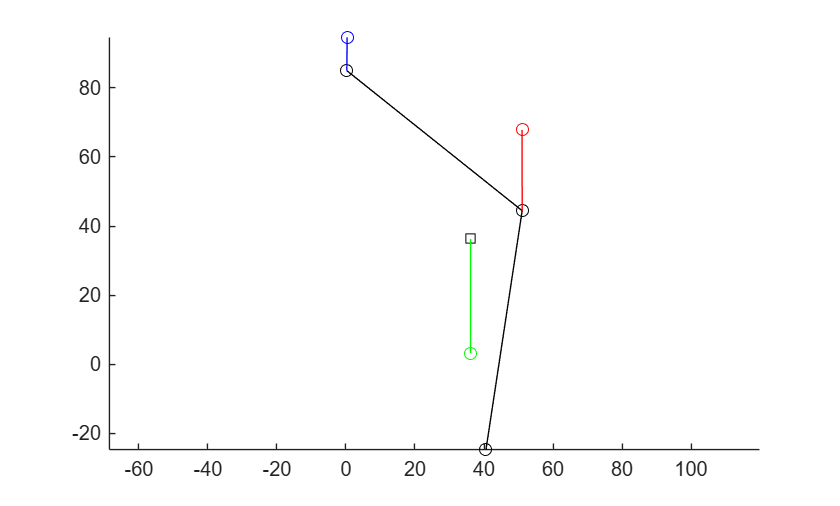

% วาดลิงก์ในหน่วย mm และให้แรง 1 N แสดงด้วยเส้นยาว 25 mm
forceScale = 25;
Cmm = 1000*C;
Dmm = 1000*D;
Fmm = 1000*F;
Gmm = 1000*G6;
tipC = Cmm + forceScale*RC;
tipD = Dmm + forceScale*RD;
tipW = Gmm + forceScale*W6;
figure()
hold on
% รูปลิงก์ C-D-F และศูนย์กลางมวล G6
plot([Cmm(1) Dmm(1) Fmm(1)], [Cmm(2) Dmm(2) Fmm(2)], '-ok')
plot(Gmm(1),Gmm(2),'sk')
% แรงที่ C สีน้ำเงิน
plot([Cmm(1) tipC(1)], [Cmm(2) tipC(2)], '-b')
plot(tipC(1),tipC(2),'ob')
% แรงที่ D สีแดง
plot([Dmm(1) tipD(1)], [Dmm(2) tipD(2)], '-r')
plot(tipD(1),tipD(2),'or')
% น้ำหนักที่ G6 สีเขียว
plot([Gmm(1) tipW(1)], [Gmm(2) tipW(2)], '-g')
plot(tipW(1),tipW(2),'og')
axis equal
hold off

Animation

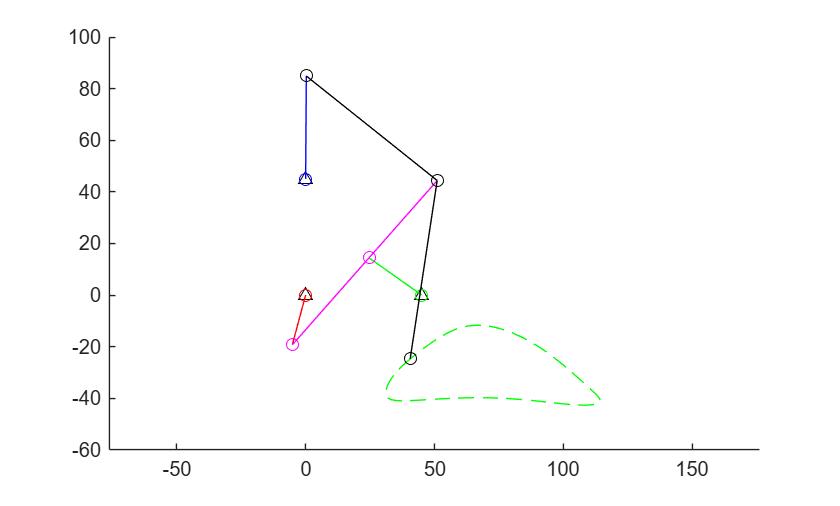

% เริ่มที่ 255 องศา หมุนตามเข็มที่ 10 rpm
q_back = @(t) q0 - omega4*t;
h_link2 = @(t) plot([O3_x Cx(q_back(t))], ...
                    [O3_y Cy(q_back(t))], '-ob');
h_link3 = @(t) plot([O1_x Ax(q_back(t))], ...
                    [O1_y Ay(q_back(t))], '-og');
h_link4 = @(t) plot([O2_x Bx(q_back(t))], ...
                    [O2_y By(q_back(t))], '-or');
h_link5 = @(t) plot([Bx(q_back(t)) Ax(q_back(t)) Dx(q_back(t))], ...
                    [By(q_back(t)) Ay(q_back(t)) Dy(q_back(t))], '-om');
h_link6 = @(t) plot([Cx(q_back(t)) Dx(q_back(t)) Fx(q_back(t))], ...
                    [Cy(q_back(t)) Dy(q_back(t)) Fy(q_back(t))], '-ok');
figure()
hold on
plot(O1_x,O1_y,'^k')
plot(O2_x,O2_y,'^k')
plot(O3_x,O3_y,'^k')
plot(foot_x,foot_y,'--g')

fanimator(h_link2,'AnimationRange',[0 T])
fanimator(h_link3,'AnimationRange',[0 T])
fanimator(h_link4,'AnimationRange',[0 T])
fanimator(h_link5,'AnimationRange',[0 T])
fanimator(h_link6,'AnimationRange',[0 T])
axis equal
hold off
playAnimation